# Pràctica 1

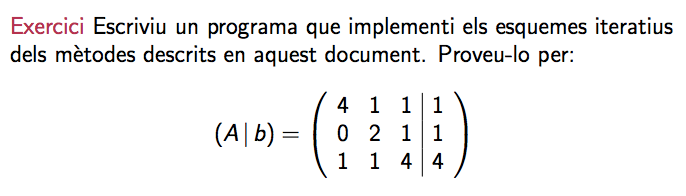

A = [4 1 1; 0 2 1; 1 1 4]

A =      4     1     1
     0     2     1
     1     1     4


b = [1 1 4]'

b =      1
     1
     4


D = diag(diag(A))

D =      4     0     0
     0     2     0
     0     0     4


d = diag(1 ./ diag(A))

d =     0.2500         0         0
         0    0.5000         0
         0         0    0.2500


E = tril(A,-1)

E =      0     0     0
     0     0     0
     1     1     0


F = triu(A,1)

F =      0     1     1
     0     0     1
     0     0     0


#### Mètode de Jacobi

Bj = -d*(E+F)

Bj =          0   -0.2500   -0.2500
         0         0   -0.5000
   -0.2500   -0.2500         0


cj = d*b

cj =     0.2500
    0.5000
    1.0000



x = [0 0 0]';
rj = zeros(10,1);
for k = [1:10]
    x = Bj * x + cj;
    rj(k) = norm(b - A * x);
end
x

x =    -0.0004
   -0.0004
    0.9996


rj

rj =     1.9526
    1.1285
    0.4648
    0.2655
    0.1207
    0.0639
    0.0308
    0.0157
    0.0078
    0.0039


#### Mètode de Gauss-Seidel

Bgs = -inv((E+D))*F

Bgs =          0   -0.2500   -0.2500
         0         0   -0.5000
         0    0.0625    0.1875


cgs = inv((E+D))*b

cgs =     0.2500
    0.5000
    0.8125



x = [0 0 0]';
rj = zeros(10,1);
for k = [1:10]
    x = Bgs * x + cgs;
    rj(k) = norm(b - A * x);
end
x

x =    -0.0000
   -0.0000
    1.0000


rj

rj =     1.5436
    0.2886
    0.0833
    0.0095
    0.0014
    0.0005
    0.0001
    0.0000
    0.0000
    0.0000


# Pràctica 2

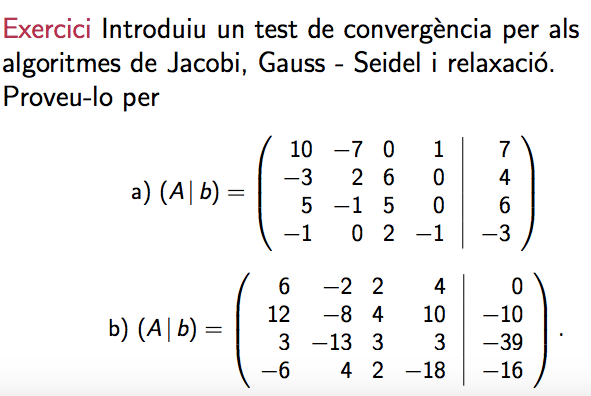

clear vars
A1 = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1]

A1 =     10    -7     0     1
    -3     2     6     0
     5    -1     5     0
    -1     0     2    -1


b1 = [7 4 6 -3]'

b1 =      7
     4
     6
    -3



A2 = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18]

A2 =      6    -2     2     4
    12    -8     4    10
     3   -13     3     3
    -6     4     2   -18


b2 = [0 -10 -39 -16]'

b2 =      0
   -10
   -39
   -16



D1 = diag(diag(A1))

D1 =     10     0     0     0
     0     2     0     0
     0     0     5     0
     0     0     0    -1


d1 = diag(1 ./ diag(A1))

d1 =     0.1000         0         0         0
         0    0.5000         0         0
         0         0    0.2000         0
         0         0         0   -1.0000


E1 = tril(A1,-1)

E1 =      0     0     0     0
    -3     0     0     0
     5    -1     0     0
    -1     0     2     0


F1 = triu(A1,1)

F1 =      0    -7     0     1
     0     0     6     0
     0     0     0     0
     0     0     0     0



D2 = diag(diag(A2))

D2 =      6     0     0     0
     0    -8     0     0
     0     0     3     0
     0     0     0   -18


d2 = diag(1 ./ diag(A2))

d2 =     0.1667         0         0         0
         0   -0.1250         0         0
         0         0    0.3333         0
         0         0         0   -0.0556


E2 = tril(A2,-1)

E2 =      0     0     0     0
    12     0     0     0
     3   -13     0     0
    -6     4     2     0


F2 = triu(A2,1)

F2 =      0    -2     2     4
     0     0     4    10
     0     0     0     3
     0     0     0     0



w = 0.3

w = 0.3000

C1 = d1

C1 =     0.1000         0         0         0
         0    0.5000         0         0
         0         0    0.2000         0
         0         0         0   -1.0000


Bsor = C1 * ((1 - w) * d1 - w * (E1 + F1))

Bsor =     0.0070    0.2100         0   -0.0300
    0.4500    0.1750   -0.9000         0
   -0.3000    0.0600    0.0280         0
   -0.3000         0    0.6000    0.7000


Csor = w * C1 * b1

Csor =     0.2100
    0.6000
    0.3600
    0.9000


r = max(abs(eig(Bsor)))

r = 0.7326

if (r > 1)
    error('No es convergent')
end

clear vars;

w = 0:0.2:2

w =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000


n = length(w)

n = 11

for k = 1:n
    Bwj = d * ((1 - w(k)) * D - w(k) * (E+F));
    rhoWJ(k) = max(abs(eig(Bwj)))
end

rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


rhoWJ =     1.0000    0.8500    0.7000    0.5500    0.4000    0.5000    0.8000    1.1000    1.4000    1.7000    2.0000


[w', rhoWJ']

ans =          0    1.0000
    0.2000    0.8500
    0.4000    0.7000
    0.6000    0.5500
    0.8000    0.4000
    1.0000    0.5000
    1.2000    0.8000
    1.4000    1.1000
    1.6000    1.4000
    1.8000    1.7000


# Pràctica 3

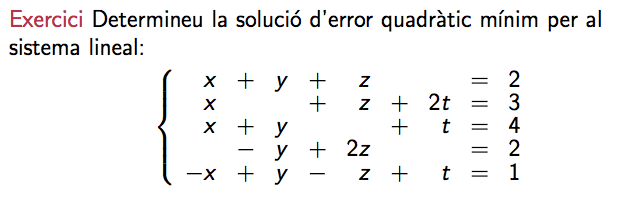

clear vars
A = [1 1 1 0; 1 0 1 2; 1 1 0 1; 0 -1 2 0; -1 1 -1 1]

A =      1     1     1     0
     1     0     1     2
     1     1     0     1
     0    -1     2     0
    -1     1    -1     1


b = [2 3 4 2 1]'

b =      2
     3
     4
     2
     1


B = A' * A

B =      4     1     3     2
     1     4    -2     2
     3    -2     7     1
     2     2     1     6


C = A' * b

C =      8
     5
     8
    11


x = B \ C

x =     0.1429
    1.2857
    1.2857
    1.1429


y = A \ b

y =     0.1429
    1.2857
    1.2857
    1.1429


r1 = norm(b-A*y)

r1 = 1.8898

z = [0 -1 2 -1]'

z =      0
    -1
     2
    -1


r2 = norm(b-A*z)

r2 = 8.9443

# Pràctica 4

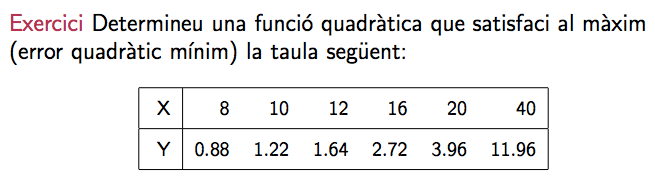

A = [8*8 8 1; 10*10 10 1; 12*12 12 1; 16*16 16 1; 20*20 20 1; 40*40 40 1]

A =           64           8           1
         100          10           1
         144          12           1
         256          16           1
         400          20           1
        1600          40           1


b = [0.88 1.22 1.64 2.72 3.96 11.96]'

b =     0.8800
    1.2200
    1.6400
    2.7200
    3.9600
   11.9600


x = A \ b

x =     0.0045
    0.1307
   -0.5166



r = norm(b-A*x)

r = 0.1054

p = polyval(x,[8 10 12 16 20 40])

p =     0.8194    1.2441    1.7050    2.7356    3.9112   11.9648


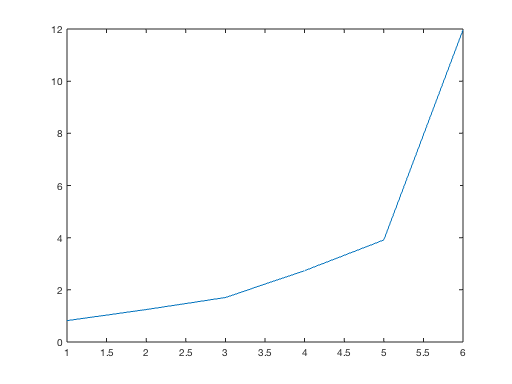

plot(p)